clear

beta = 0.08

beta = 0.0800

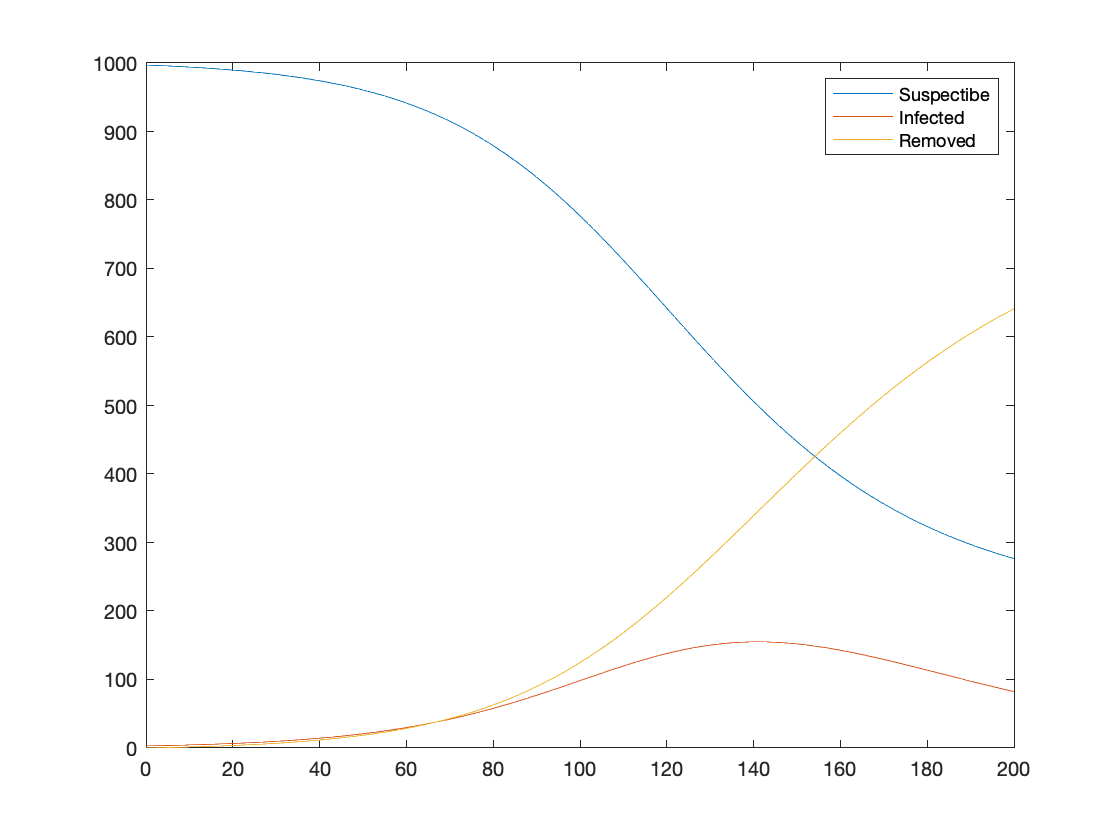


F = SIRF(0.04, 0, 0, beta);

[t, y] = rungekutta(F, [0, 200], 1, [997, 3, 0]);

plot(t, y)
legend('Suspectibe', 'Infected', 'Removed')

function F = SIRF(gamma, mu, nu, beta)
    function yp = m(~, y)
        S = y(1);
        I = y(2);
        R = y(3);
        N = S + I + R;
        
        Sd = nu * N - beta * S * I / N - mu * S;
        Id = beta * S * I / N - gamma * I - mu * I;
        Rd = gamma * I - mu * R;
        
        yp = [Sd; Id; Rd];
    end
    F = @m;
end